% Extract the names of all the data files
allFiles = dir("data");
allFiles = struct2cell(allFiles);
n = size(allFiles);
n = n(2);
allFiles = allFiles(1,3:n) % remove the '.' and '..' elements returned by dir

allFiles = 1×5 cell array
    {'final_results_202407041000.json'}    {'final_results_202407151100_D.json'}    {'final_results_202407151100_L.json'}    {'final_results_202407151300_D.json'}    {'final_results_202407151300_L.json'}


n = size(allFiles);
n = n(2);

short_sims = zeros(1, n*90);
long_sims = zeros(1, n*90);

% For each data file, calculate the similarity between the stimulus and
% response for each trial, separate the short and long stimulus duration
% trials, and save the data
for p = 1:n
    % Load the data from a file and decode the json into a Matlab struct
    fileName = strcat('data/', allFiles{p})
    fid = fopen(fileName);
    raw = fread(fid,inf);
    str = char(raw');
    data = jsondecode(str); % this creates a list of structs describing each jsPsych component in the experiment'

    % Create a table with only the main experiment sketchpad trials
    img_data = {};
    for k = 1:size(data, 1)
        temp = struct2table(data{k}, AsArray=true); % read the information about the current jsPsych component into a table format
        if strcmp( temp.trial_type{1}, 'sketchpad' ) && strcmp( temp.task{1}, 'main_experiment' ) % filter out everything besides the main experiment sketchapd trials
            if isempty(img_data) % if this is the first trial, make it the image data table,
                img_data = temp;
            else % otherwise just append the current trial to the image data table
                img_data = [img_data; temp];
            end
        end
    end
    
    % Extract the images from from the data
    org_images = img_data.png;

    len = size(org_images);
    len = len(1);
    
    % Extract all the drawing images from the data
    images = zeros(len, 700, 1500, 3);
    complete = zeros(len, 1);
    for i = 1:len
        images(i, :, :, :) = dataURLtoImage(org_images{i}, i);
        complete(i) = checkCompleteness(squeeze(images(i, :, :, :)));
    end
    
    % Extract all the stimuli images from the data
    stimuli = img_data.stimulus_path;
    stim_images = zeros(len, 280, 280);
    for i = 1:len
        stim_images(i, :, :) = imread(stimuli{i});
    end

    % find the turning distance similarity measure between each stimulus and
    % participant's drawing
    similarity = zeros(len, 1);
    for i = 1:len
        if complete(i)
            drawing = imageToPolygon(squeeze(images(i, :, :, :)), 1, 0);
            stim = imageToPolygon(squeeze(stim_images(i, :, :)), 1, 0);
            similarity(i) = turningdist(drawing, stim);
        end
    end

    % Save the similarities for short and long stimulus durations to separate
    % arrays
    short = zeros(1, len/2);
    short_i = 1;
    long = zeros(1, len/2);
    long_i = 1;
    for i = 1:len
        if similarity(i) ~= 0 % 0 is saved when the drawing is incomplete
            if img_data.stim_dur(i) == 1000
                long(long_i) = similarity(i);
                long_i = long_i + 1;
            else
                short(short_i) = similarity(i);
                short_i = short_i + 1;
            end
        else % when the drawing is incomplete, save a NaN which will be ignored in subsequent statistical analysis
           if img_data.stim_dur(i) == 1000
                long(long_i) = NaN;
                long_i = long_i + 1;
            else
                short(short_i) = NaN;
                short_i = short_i + 1;
           end
        end
    end

    % Save the similarity measures to the global arrays
    for i = 1:len/2
        short_sims((p-1)*len/2 + i) = short(i);
        long_sims((p-1)*len/2 + i) = long(i);
    end

end

fileName = 'data/final_results_202407041000.json'

fileName = 'data/final_results_202407151100_D.json'

fileName = 'data/final_results_202407151100_L.json'

fileName = 'data/final_results_202407151300_D.json'

fileName = 'data/final_results_202407151300_L.json'

short_sims

short_sims =     0.7747    0.7724    0.7445    0.7713    0.7370    0.7430    0.7270    0.8177    0.6995    0.6661    0.6950    0.7020    0.7612    0.7995    0.7881    0.7182    0.6601    0.8176    0.7003    0.7162    1.7163    0.6341    0.8225    0.6418    0.6893    0.8333    0.6927    0.8209    0.7130    0.7713    0.9076    0.7827    0.7236    0.8476    0.7170    0.6962    0.6832    0.6470    0.7687    0.6733    0.7078    0.8084    0.6945       NaN    0.6575    0.7462    0.7680    0.7320    0.6544    0.7068


long_sims

long_sims =     0.6893    0.8574    0.8735    1.0597    0.7237    0.7020    0.6699    0.6583    0.6693    0.6792    0.6523    0.7885    0.7789    0.6955    0.6663    0.7291    0.8174    0.8209    0.7301    0.8304    0.7251    0.6695    0.6084    0.6647    0.7671       NaN    0.8376    0.6707    0.7295    0.6783    0.7281    0.7363    0.7413    0.8266    0.8208    0.8892    0.6871    0.6783    0.6913    0.7135    0.8348    0.8501    0.6751    0.7089    0.7969    0.6220    0.7091    0.6537    0.6228    0.7458


short_sims_excluded =     0.7747    0.7724    0.7445    0.7713    0.7370    0.7430    0.7270    0.8177    0.6995    0.6661    0.6950    0.7020    0.7612    0.7995    0.7881    0.7182    0.6601    0.8176    0.7003    0.7162    0.6341    0.8225    0.6418    0.6893    0.8333    0.6927    0.8209    0.7130    0.7713    0.9076    0.7827    0.7236    0.8476    0.7170    0.6962    0.6832    0.6470    0.7687    0.6733    0.7078    0.8084    0.6945    0.6575    0.7462    0.7680    0.7320    0.6544    0.7068    0.8271    0.8895


long_sims_excluded =     0.6893    0.8574    0.8735    0.7237    0.7020    0.6699    0.6583    0.6693    0.6792    0.6523    0.7885    0.7789    0.6955    0.6663    0.7291    0.8174    0.8209    0.7301    0.8304    0.7251    0.6695    0.6084    0.6647    0.7671    0.8376    0.6707    0.7295    0.6783    0.7281    0.7363    0.7413    0.8266    0.8208    0.8892    0.6871    0.6783    0.6913    0.7135    0.8348    0.8501    0.6751    0.7089    0.7969    0.6220    0.7091    0.6537    0.6228    0.7458    0.7952    0.8059


mean_short = nanmean(short_sims)

mean_short = 0.7690

std_short = std(short_sims, "omitmissing")

std_short = 0.1210

mean_long = nanmean(long_sims)

mean_long = 0.7569

std_long = std(long_sims, "omitmissing")

std_long = 0.1186

short_sims_exc = short_sims(short_sims > mean_short - 3*std_short & short_sims < mean_short + 3*std_short)

short_sims_exc =     0.7747    0.7724    0.7445    0.7713    0.7370    0.7430    0.7270    0.8177    0.6995    0.6661    0.6950    0.7020    0.7612    0.7995    0.7881    0.7182    0.6601    0.8176    0.7003    0.7162    0.6341    0.8225    0.6418    0.6893    0.8333    0.6927    0.8209    0.7130    0.7713    0.9076    0.7827    0.7236    0.8476    0.7170    0.6962    0.6832    0.6470    0.7687    0.6733    0.7078    0.8084    0.6945    0.6575    0.7462    0.7680    0.7320    0.6544    0.7068    0.8271    0.8895


long_sims_exc = short_sims(long_sims > mean_long - 3*std_long & long_sims < mean_long + 3*std_long)

long_sims_exc =     0.7747    0.7724    0.7445    0.7713    0.7370    0.7430    0.7270    0.8177    0.6995    0.6661    0.6950    0.7020    0.7612    0.7995    0.7881    0.7182    0.6601    0.8176    0.7003    0.7162    1.7163    0.6341    0.8225    0.6418    0.6893    0.6927    0.8209    0.7130    0.7713    0.9076    0.7827    0.7236    0.8476    0.7170    0.6962    0.6832    0.6470    0.7687    0.6733    0.7078    0.8084    0.6945       NaN    0.6575    0.7462    0.7680    0.7320    0.6544    0.7068    0.8895


nanmean(short_sims_exc)

ans = 0.7626

nanmean(long_sims_exc)

ans = 0.7665

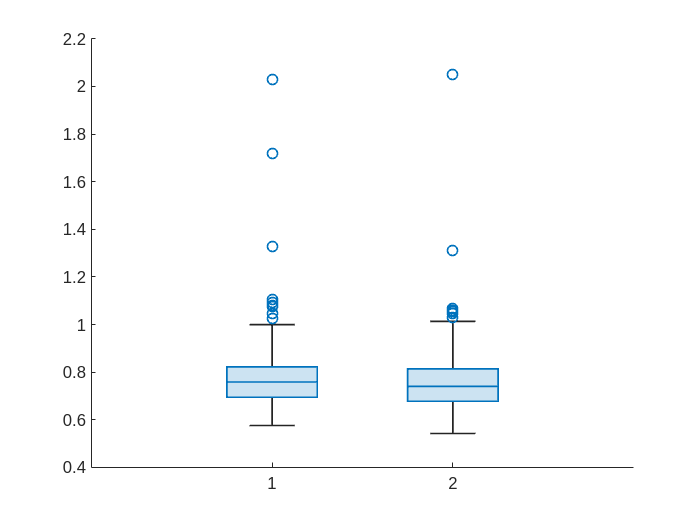

boxchart(transpose([short_sims; long_sims]))

[h,p,ci,stats] = ttest2(short_sims_exc, long_sims_exc)

h = 0

p = 0.5696

ci =    -0.0170    0.0094


stats = struct with fields:
    tstat: -0.5689
       df: 858
       sd: 0.0987
